# Lab 5

Jessie Li // October 25, 2023

##  1.

E = 10^-9;
N_MAX = 25;

% Functions
f_a = @(x) x.^2 .* exp(-x.^2);
f_b = @(x) x.^(1/2) .* exp(-x.^2);

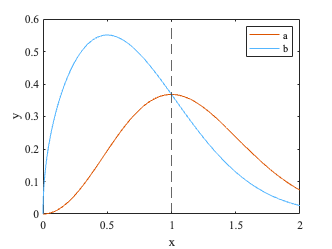

% Plot functions
x = 0:1e-3:2;

figure

colororder('reef')
set(groot, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 12)
set(groot, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 14)

plot(x, f_a(x), x, f_b(x))
xline(1, '--')

legend('a', 'b', 'Location', 'northeast')

xlabel('x')
ylabel('y')

saveas(gcf, 'lab5/functions.png')

% Function (a) with limits of integration from 0 to 1
fprintf('--------------------------------------------------\n')

--------------------------------------------------


fprintf('Function (a) with limits of integration from 0 to 1')

Function (a) with limits of integration from 0 to 1


[R, n_romberg] = romberg(f_a, 0, 1, E, N_MAX);

(Romberg) n: 6
(Romberg) Approximation: 0.18947
(Romberg) Number of function evaluations: 134

[T, n_trapezoidal] = trapezoidal(f_a, 0, 1, E, N_MAX);

(Trapezoidal) n: 7
(Trapezoidal) Approximation: 0.18947
(Trapezoidal) Number of function evaluations: 129

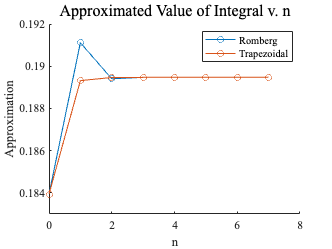

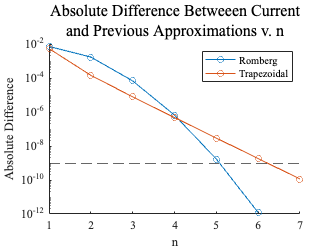


plot_romberg_trapezoidal(R, n_romberg, T, n_trapezoidal, 'lab5/a01')


R_a_01 = R(n_romberg+1, n_romberg+1);

% Function (a) with limits of integration from 1 to 2
fprintf('--------------------------------------------------\n')

--------------------------------------------------


fprintf('Function (a) with limits of integration from 1 to 2')

Function (a) with limits of integration from 1 to 2


[R, n_romberg] = romberg(f_a, 1, 2, E, N_MAX);

(Romberg) n: 5
(Romberg) Approximation: 0.23325
(Romberg) Number of function evaluations: 69

[T, n_trapezoidal] = trapezoidal(f_a, 1, 2, E, N_MAX);

(Trapezoidal) n: 13
(Trapezoidal) Approximation: 0.23325
(Trapezoidal) Number of function evaluations: 8193

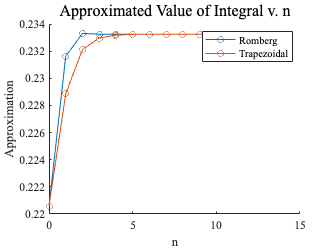

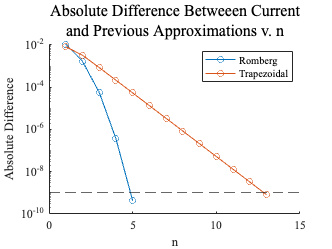


plot_romberg_trapezoidal(R, n_romberg, T, n_trapezoidal, 'lab5/a12')


R_a_12 = R(n_romberg+1, n_romberg+1);

% Function (b) with limits of integration from 0 to 1
fprintf('--------------------------------------------------\n')

--------------------------------------------------


fprintf('Function (b) with limits of integration from 0 to 1')

Function (b) with limits of integration from 0 to 1


[R, n_romberg] = romberg(f_b, 0, 1, E, N_MAX);

(Romberg) n: 18
(Romberg) Approximation: 0.45339
(Romberg) Number of function evaluations: 524306

[T, n_trapezoidal] = trapezoidal(f_b, 0, 1, E, N_MAX);

(Trapezoidal) n: 20
(Trapezoidal) Approximation: 0.45339
(Trapezoidal) Number of function evaluations: 1048577

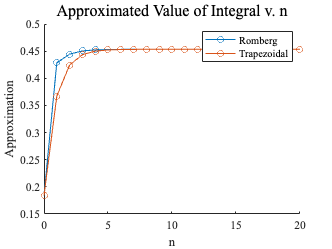

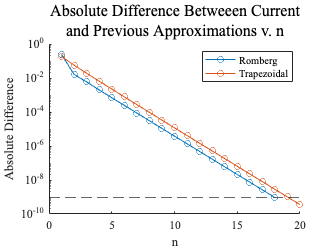


plot_romberg_trapezoidal(R, n_romberg, T, n_trapezoidal, 'lab5/b01')


R_b_01 = R(n_romberg+1, n_romberg+1);

% Function (b) with limits of integration from 1 to 2
fprintf('--------------------------------------------------\n')

--------------------------------------------------


fprintf('Function (b) with limits of integration from 1 to 2')

Function (b) with limits of integration from 1 to 2


[R, n_romberg] = romberg(f_b, 1, 2, E, N_MAX);

(Romberg) n: 5
(Romberg) Approximation: 0.15316
(Romberg) Number of function evaluations: 69

[T, n_trapezoidal] = trapezoidal(f_b, 1, 2, E, N_MAX);

(Trapezoidal) n: 14
(Trapezoidal) Approximation: 0.15316
(Trapezoidal) Number of function evaluations: 16385

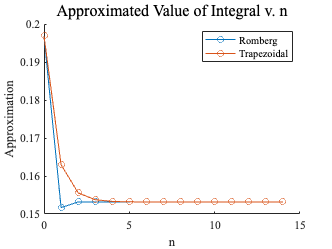

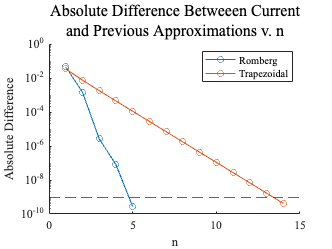


plot_romberg_trapezoidal(R, n_romberg, T, n_trapezoidal, 'lab5/b12')


R_b_12 = R(n_romberg+1, n_romberg+1);

## 2.

% Gauss points and weights from:
% https://pomax.github.io/bezierinfo/legendre-gauss.html

max_n = 11;
a_01 = zeros(max_n, 1);
a_12 = zeros(max_n, 1);
b_01 = zeros(max_n, 1);
b_12 = zeros(max_n, 1);

% n = 1
ai_xi1 = [2, 0];

% n = 2
ai_xi2 = [
    1.0000000000000000,	-0.5773502691896257;
    1.0000000000000000,	0.5773502691896257
];

% n = 3
ai_xi3 = [
    0.8888888888888888,	0.0000000000000000;
    0.5555555555555556,	-0.7745966692414834;
    0.5555555555555556,	0.7745966692414834
];

% n = 4
ai_xi4 = [
    0.6521451548625461,	-0.3399810435848563;
    0.6521451548625461,	0.3399810435848563;
    0.3478548451374538,	-0.8611363115940526;
    0.3478548451374538,	0.8611363115940526
];

% n = 5
ai_xi5 = [
    0.5688888888888889, 0.0000000000000000;
    0.4786286704993665,	-0.5384693101056831;
    0.4786286704993665,	0.5384693101056831;
    0.2369268850561891,	-0.9061798459386640;
    0.2369268850561891,	0.9061798459386640
];    

% n = 6
ai_xi6 = [
    0.3607615730481386,	0.6612093864662645;
    0.3607615730481386,	-0.6612093864662645;
	0.4679139345726910,	-0.2386191860831969;
	0.4679139345726910,	0.2386191860831969;
	0.1713244923791704,	-0.9324695142031521;
	0.1713244923791704,	0.9324695142031521
];

% n = 7
ai_xi7 = [
    0.4179591836734694,	0.0000000000000000;
	0.3818300505051189,	0.4058451513773972;
	0.3818300505051189,	-0.4058451513773972;
	0.2797053914892766,	-0.7415311855993945;
	0.2797053914892766,	0.7415311855993945;
	0.1294849661688697,	-0.9491079123427585;
	0.1294849661688697,	0.9491079123427585;
];

% n = 8
ai_xi8 = [
    0.3626837833783620,	-0.1834346424956498;
    0.3626837833783620,	0.1834346424956498;
    0.3137066458778873,	-0.5255324099163290;
    0.3137066458778873,	0.5255324099163290;
    0.2223810344533745,	-0.7966664774136267;
    0.2223810344533745,	0.7966664774136267;
    0.1012285362903763,	-0.9602898564975363;
    0.1012285362903763,	0.9602898564975363
];

% n = 9
ai_xi9 = [
    0.3302393550012598,	0.0000000000000000;
    0.1806481606948574,	-0.8360311073266358;
    0.1806481606948574,	0.8360311073266358;
    0.0812743883615744,	-0.9681602395076261;
    0.0812743883615744,	0.9681602395076261;
    0.3123470770400029,	-0.3242534234038089;
    0.3123470770400029,	0.3242534234038089;
    0.2606106964029354,	-0.6133714327005904;
    0.2606106964029354,	0.6133714327005904
];

% n = 10
ai_xi10 = [
    0.2955242247147529,	-0.1488743389816312;
    0.2955242247147529,	0.1488743389816312;
    0.2692667193099963,	-0.4333953941292472;
    0.2692667193099963,	0.4333953941292472;
    0.2190863625159820,	-0.6794095682990244;
    0.2190863625159820,	0.6794095682990244;
    0.1494513491505806,	-0.8650633666889845;
    0.1494513491505806,	0.8650633666889845;
    0.0666713443086881,	-0.9739065285171717;
    0.0666713443086881,	0.9739065285171717
];

% n = 11
ai_xi11 = [
    0.2729250867779006,	0.0000000000000000;
    0.2628045445102467,	-0.2695431559523450;
    0.2628045445102467,	0.2695431559523450;
    0.2331937645919905,	-0.5190961292068118;
    0.2331937645919905,	0.5190961292068118;
    0.1862902109277343,	-0.7301520055740494;
    0.1862902109277343,	0.7301520055740494;
    0.1255803694649046,	-0.8870625997680953;
    0.1255803694649046,	0.8870625997680953;
    0.0556685671161737,	-0.9782286581460570;
    0.0556685671161737,	0.9782286581460570;
];

ai_xi = [
    ai_xi1; ai_xi2; ai_xi3; 
    ai_xi4; ai_xi5; ai_xi6; 
    ai_xi7; ai_xi8; ai_xi9; 
    ai_xi10; ai_xi11
];


row = 1

row = 1


for n = 1 : max_n
    fprintf('n = %d --------------------------------------------------\n', n)
    ai = ai_xi(row:row + n - 1, 1);
    xi = ai_xi(row:row + n - 1, 2);
 
    % fprintf('Function (a) with limits of integration from 0 to 1')
    a_01(n) = gaussian(f_a, 0, 1, n, ai, xi);

    % fprintf('Function (a) with limits of integration from 1 to 2')
    a_12(n) = gaussian(f_a, 1, 2, n, ai, xi);
 
    % fprintf('Function (b) with limits of integration from 0 to 1')
    b_01(n) = gaussian(f_b, 0, 1, n, ai, xi);
 
    % fprintf('Function (b) with limits of integration from 1 to 2')
    b_12(n) = gaussian(f_b, 1, 2, n, ai, xi);

    % fprintf('Number of function evaluations: %d\n', n);
    
    row = row + n;
end

n = 1 --------------------------------------------------


Gaussian approximation: 0.19470
Evaluations: 1



Gaussian approximation: 0.23715
Evaluations: 1



Gaussian approximation: 0.55070
Evaluations: 1



Gaussian approximation: 0.12909
Evaluations: 1



n = 2 --------------------------------------------------


Gaussian approximation: 0.18832
Evaluations: 2



Gaussian approximation: 0.23439
Evaluations: 2



Gaussian approximation: 0.45820
Evaluations: 2



Gaussian approximation: 0.15414
Evaluations: 2



n = 3 --------------------------------------------------


Gaussian approximation: 0.18954
Evaluations: 3



Gaussian approximation: 0.23320
Evaluations: 3



Gaussian approximation: 0.45590
Evaluations: 3



Gaussian approximation: 0.15316
Evaluations: 3



n = 4 --------------------------------------------------


Gaussian approximation: 0.18947
Evaluations: 4



Gaussian approximation: 0.23325
Evaluations: 4



Gaussian approximation: 0.45455
Evaluations: 4



Gaussian approximation: 0.15316
Evaluations: 4



n = 5 --------------------------------------------------


Gaussian approximation: 0.18947
Evaluations: 5



Gaussian approximation: 0.23325
Evaluations: 5



Gaussian approximation: 0.45402
Evaluations: 5



Gaussian approximation: 0.15316
Evaluations: 5



n = 6 --------------------------------------------------


Gaussian approximation: 0.18947
Evaluations: 6



Gaussian approximation: 0.23325
Evaluations: 6



Gaussian approximation: 0.45377
Evaluations: 6



Gaussian approximation: 0.15316
Evaluations: 6



n = 7 --------------------------------------------------


Gaussian approximation: 0.18947
Evaluations: 7



Gaussian approximation: 0.23325
Evaluations: 7



Gaussian approximation: 0.45364
Evaluations: 7



Gaussian approximation: 0.15316
Evaluations: 7



n = 8 --------------------------------------------------


Gaussian approximation: 0.18947
Evaluations: 8



Gaussian approximation: 0.23325
Evaluations: 8



Gaussian approximation: 0.45356
Evaluations: 8



Gaussian approximation: 0.15316
Evaluations: 8



n = 9 --------------------------------------------------


Gaussian approximation: 0.18947
Evaluations: 9



Gaussian approximation: 0.23325
Evaluations: 9



Gaussian approximation: 0.45351
Evaluations: 9



Gaussian approximation: 0.15316
Evaluations: 9



n = 10 --------------------------------------------------


Gaussian approximation: 0.18947
Evaluations: 10



Gaussian approximation: 0.23325
Evaluations: 10



Gaussian approximation: 0.45348
Evaluations: 10



Gaussian approximation: 0.15316
Evaluations: 10



n = 11 --------------------------------------------------


Gaussian approximation: 0.18947
Evaluations: 11



Gaussian approximation: 0.23325
Evaluations: 11



Gaussian approximation: 0.45346
Evaluations: 11



Gaussian approximation: 0.15316
Evaluations: 11




t = table((1 : max_n).', a_01, a_12, b_01, b_12)

t = 11×5 table
    Var1     a_01       a_12       b_01       b_12  
    ____    _______    _______    _______    _______

      1      0.1947    0.23715     0.5507    0.12909
      2     0.18832    0.23439     0.4582    0.15414
      3     0.18954     0.2332     0.4559    0.15316
      4     0.18947    0.23325    0.45455    0.15316
      5     0.18947    0.23325    0.45402    0.15316
      6     0.18947    0.23325    0.45377    0.15316
      7     0.18947    0.23325    0.45364    0.15316
      8     0.18947    0.23325    0.45356    0.15316
      9     0.18947    0.23325    0.45351    0.15316
     10     0.18947    0.23325    0.45348    0.15316
     11     0.18947    0.23325    0.45346    0.15316


fprintf('Function (a) with limits of integration from 0 to 1');

Function (a) with limits of integration from 0 to 1

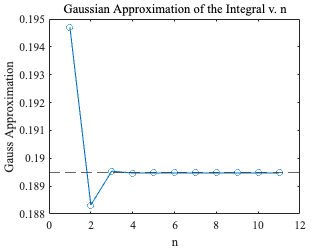

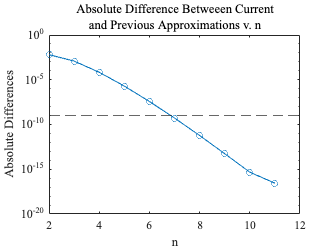

plot_gaussian_results(a_01, max_n, R_a_01, 'lab5/a01')


fprintf('Function (a) with limits of integration from 1 to 2')

Function (a) with limits of integration from 1 to 2

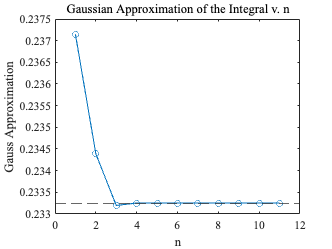

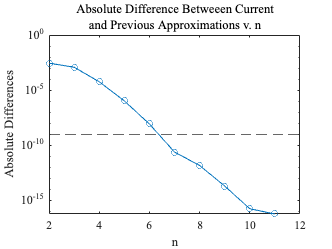

plot_gaussian_results(a_12, max_n, R_a_12, 'lab5/a12')


fprintf('Function (b) with limits of integration from 0 to 1')

Function (b) with limits of integration from 0 to 1

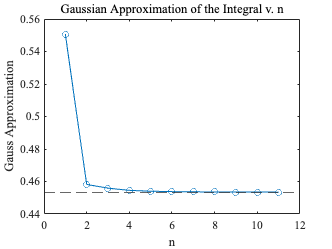

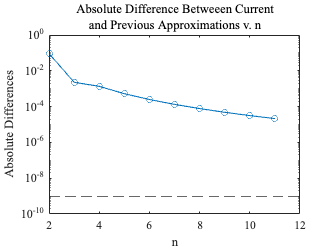

plot_gaussian_results(b_01, max_n, R_b_01, 'lab5/b01')


fprintf('Function (b) with limits of integration from 1 to 2')

Function (b) with limits of integration from 1 to 2

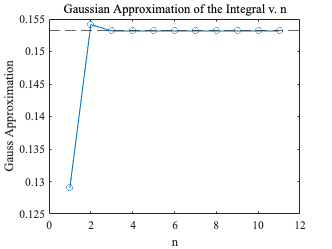

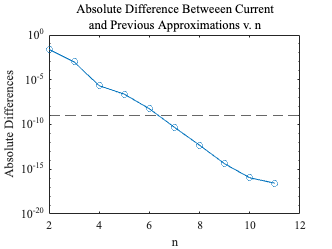

plot_gaussian_results(b_12, max_n, R_b_12, 'lab5/b12')

## 3.

% Interval a <= t <= b
a = 0;
b = 3;

% Initial value problem
dy_dt = @(y, t) -2 * y * t / (1 + t^2);
y0 = 1;

% Analytical solution
y = @(t) 1 ./ (1 + t.^2);

n_min = 3;
n_max = 12;

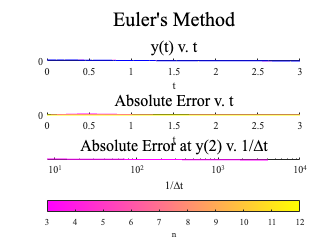

% Euler's method
y2_error_euler = approximate(dy_dt, y0, y, a, b, n_min, n_max, @euler, 'Euler''s Method');
saveas(gcf, 'lab5/euler.png');

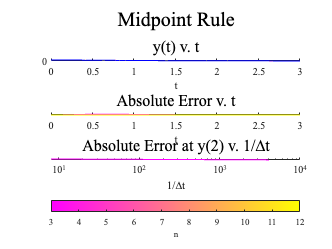

% Midpoint rule
y2_error_midpoint = approximate(dy_dt, y0, y, a, b, n_min, n_max, @midpoint_rule, 'Midpoint Rule');
saveas(gcf, 'lab5/midpoint.png')

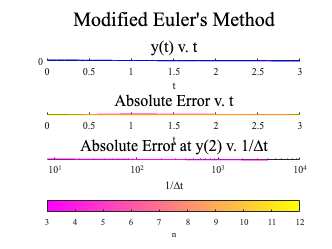

% Modified Euler’s method
y2_error_modified_euler = approximate(dy_dt, y0, y, a, b, n_min, n_max, @modified_euler, 'Modified Euler''s Method');
saveas(gcf, 'lab5/modified_euler.png')

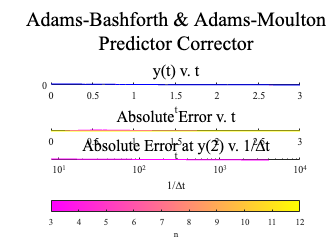

% 2-step Adams-Bashforth/Adams-Moulton predictor corrector
y2_error_adams = approximate(dy_dt, y0, y, a, b, n_min, n_max, @adams, {'Adams-Bashforth & Adams-Moulton', 'Predictor Corrector'});
saveas(gcf, 'lab5/adams.png')

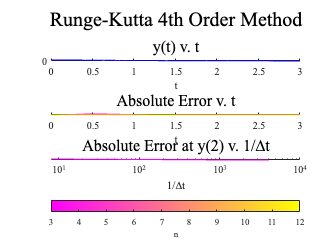

% Runge-Kutta 4th order method
y2_error_runge_kutta = approximate(dy_dt, y0, y, a, b, n_min, n_max, @runge_kutta_4, 'Runge-Kutta 4th Order Method');
saveas(gcf, 'lab5/runge_kutta.png')

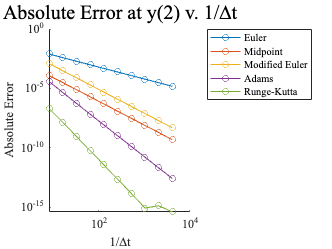

% All y(2) v. 1/∆t
inverse_delta_t = 2 .^ (n_min : n_max);

figure
hold on

set(groot, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 12)
set(groot, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 14)

plot(inverse_delta_t, y2_error_euler, '-o');
plot(inverse_delta_t, y2_error_midpoint, '-o');
plot(inverse_delta_t, y2_error_modified_euler, '-o')
plot(inverse_delta_t, y2_error_adams, '-o');
plot(inverse_delta_t, y2_error_runge_kutta, '-o');

hold off

set(gca, 'YScale', 'log', 'XScale', 'log')

xlabel('1/∆t')
ylabel('Absolute Error')

title('Absolute Error at y(2) v. 1/∆t', 'FontSize', 20, 'FontWeight', 'normal');
legend({'Euler', 'Midpoint', 'Modified Euler', 'Adams', 'Runge-Kutta'}, 'Location', 'bestoutside');

saveas(gcf, 'lab5/y2_errors.png')

## Functions

function [R, n, romberg_evaluations] = romberg(f, a, b, e, n_max)
    %{
        Approximates the integral from a to b of f(x) with Romberg's method.
        
        Input:
            f: function
            a: lower limit
            b: upper limit
            e: error
        
        Returns:
            R: Romberg approximation
            n: number of times subintervals were halved
            romberg_evaluations: number of function evaluations
    %}
        
    R = zeros(n_max + 1, n_max + 1);
    romberg_evaluations = 0;
    
    % Calculate the Romberg table row by row
    for n = 0 : n_max
        for j = 0 : n
       
            % Initialize R with a composite trapezoidal approximation
            if j == 0
                [R(n+1, j+1), trapezoidal_evaluations] = composite_trapezoidal(f, a, b, 2^n);
                romberg_evaluations = romberg_evaluations + trapezoidal_evaluations;

            else
                R(n+1, j+1) = (4^j * R(n+1, j) - R(n, j)) / (4^j - 1);

            end
        end

        % Check if R(n, n) is close enough to R(n-1, n-1)
        if n > 0 && abs(R(n+1, n+1) - R(n, n)) < e
            break;
        end
    end

    fprintf('(Romberg) n: %d\n', n);
    fprintf('(Romberg) Approximation: %0.5f\n', R(n+1, n+1));
    fprintf('(Romberg) Number of function evaluations: %d', romberg_evaluations);
end

function [I, n, trapezoidal_evaluations] = trapezoidal(f, a, b, e, n_max)
    %{
        Approximates the integral from a to b of f(x) with the Composite
        Trapezoidal rule.
        
        Input:
            f: function
            a: lower limit
            b: upper limit
            e: error
        
        Returns:
            I: Composite Trapezoidal approximation
            n: number of times subintervals were halved
            trapezoidal_evaluations: number of function evaluations
    %}

    I = zeros(n_max + 1, 1);
    trapezoidal_evaluations = 0;
    
    for n = 0 : n_max
        [I(n+1), trapezoidal_evaluations] = composite_trapezoidal(f, a, b, 2^n);
        
        % Check if I(n) is close enough to I(n-1)
        if n > 0 && abs(I(n+1) - I(n)) < e
            break;
        end
    end

    fprintf('(Trapezoidal) n: %d\n', n);
    fprintf('(Trapezoidal) Approximation: %0.5f\n', I(n+1));
    fprintf('(Trapezoidal) Number of function evaluations: %d', trapezoidal_evaluations);
end

function [I, evaluations] = composite_trapezoidal(f, a, b, n)
    %{
        Approximates the integral from a to b of f(x) with n subintervals.
        
        Input:
            f: function
            a: lower limit
            b: upper limit
            n: number of subintervals
        
        Returns:
            I:  approximated value of integral
            evaluations: number of function evaluations
    %}

    h = (b - a)/n;
    I = 0;
    evaluations = 0;
    
    for i = 0 : n
        x = a + i * h;

        if i == 0 || i == n
            I = I + f(x);
        else
            I = I + 2 * f(x);
        end
        
        evaluations = evaluations + 1;
    end

    I = I * h/2;
end

function plot_romberg_trapezoidal(R, n_romberg, T, n_trapezoidal, file)
    %{
        Plots approximated value of integral v. n.
        Plots absolute differences v. n.
        
        Input:
            R: Romberg table
            n_romberg: number of steps (2^n)
            T: Trapezoidal approximations
            n_trapezoidal: number of steps (2^n)
            file: output file prefix
    %}

    % Get Romberg approximations along the diagonal
    romberg_approximations = zeros(n_romberg + 1, 1);
    for i = 1 : n_romberg + 1
        romberg_approximations(i) = R(i, i);
    end

    trapezoidal_approximations = T(1:n_trapezoidal + 1);

    title_font = {'FontSize', 16, 'FontWeight', 'normal'};

    % Plot approximations v. n
    figure

    set(groot, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 12)
    set(groot, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 14)

    hold on
    plot(0:n_romberg, romberg_approximations, '-o')
    plot(0:n_trapezoidal, trapezoidal_approximations, '-o')
    hold off
    
    legend('Romberg', 'Trapezoidal', 'Location', 'northeast')

    xlabel('n')
    ylabel('Approximation')
    title('Approximated Value of Integral v. n', title_font{:})
    
    saveas(gcf, sprintf('%s-rt-approx.png', file))

    % Compute errors
    romberg_errors = zeros(n_romberg, 1);
    for i = 1 : n_romberg
        romberg_errors(i) = abs(R(i+1, i+1) - R(i, i));
    end

    trapezoidal_errors = zeros(n_trapezoidal, 1);
    for i = 1 : n_trapezoidal
        trapezoidal_errors(i) = abs(T(i+1) - T(i));
    end

    % Plot errors v. n
    figure

    set(groot, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 12)
    set(groot, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 14)

    hold on
    plot(1:n_romberg, romberg_errors, '-o')
    plot(1:n_trapezoidal, trapezoidal_errors, '-o')
    yline(1e-9, '--')
    hold off
    
    set(gca, 'YScale', 'log')
    legend('Romberg', 'Trapezoidal', 'Location', 'northeast')

    xlabel('n')
    ylabel('Absolute Difference')
    title({'Absolute Difference Betweeen Current', 'and Previous Approximations v. n'}, title_font{:})

    saveas(gcf, sprintf('%s-rt-diff.png', file))

end

function [G, evaluations] = gaussian(f, a, b, n, ai, xi)
    %{
        Approximates the integral from a to b of f(x) with Gaussian quadrature.
        
        Input:
            f: function
            a: lower limit
            b: upper limit
            n: number of points
            ai: coefficients
            xi: Gauss points
        
        Returns:
            G: approximated value of integral
            evaluations: number of function evaluations
    %}
        % Map Gauss points from (-1, 1) to (a, b)
        yi = (a+b)/2 + (b-a)/2 .* xi;
        
    G = 0;
    evaluations = 0;

    for i = 1 : n
        G = G + ai(i) * f(yi(i));
        evaluations = evaluations + 1;
    end

    G = (b-a)/2 * G;
    
    fprintf('Gaussian approximation: %0.5f\n', G);
    fprintf('Evaluations: %d\n\n', evaluations);
end

function plot_gaussian_results(G, n, romberg_approximation, file)
    %{
        Plots results of the Gaussian quadrature.
        
        Input:
            G: Gaussian approximations
            n: maximum number of points (1 to n)
            romberg_approximation: Romberg value of the integral
            file: output file prefix
    %}

    title_font = {'FontSize', 16, 'FontWeight', 'normal'};

    % Plot approximation v. n, with a yline for Romberg approximation
    figure

    set(groot, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 12)
    set(groot, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 14)

    plot(1:n, G, '-o')
    yline(romberg_approximation, '--')

    xlabel('n')
    ylabel('Gauss Approximation')
    title('Gaussian Approximation of the Integral v. n', title_font{:})

    saveas(gcf, sprintf('%s-g-approx.png', file))

    % Plot differences v. n
    gaussian_differences = zeros(n-1);

    for i = 1:n-1
        gaussian_differences(i) = abs(G(i+1) - G(i));
    end

    figure

    set(groot, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 12)
    set(groot, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 14)

    plot(2:n, gaussian_differences, '-o')
    yline(1e-9, '--')

    set(gca, 'YScale', 'log')

    xlabel('n')
    ylabel('Absolute Differences')
    title({'Absolute Difference Betweeen Current', 'and Previous Approximations v. n'}, title_font{:})
    
    saveas(gcf, sprintf('%s-g-diff.png', file))
end

function w = euler(dy_dt, a, b, h, y0)
    %{
        Performs Euler's method to approximate y(t) given dy/dt and h.
        
        Input:
            dy_dt: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
        
        Returns:
            w: approximated y values
    %}
    
    % Number of subintervals
    n = (b - a) / h;
    
    w = zeros(n + 1, 1);
    w(1) = y0;
    
    for i = 1 : n
        t = a + (i-1) * h;
        w(i + 1) = w(i) + h * dy_dt(w(i), t);
    end
end

function w = midpoint_rule(dy_dt, a, b, h, y0)
     %{
        Uses the midpoint rule (RK-2) to approximate y(t) given dy/dt and h.
        
        Input:
            dy_dt: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
        
        Returns:
            w: approximated y values
     %}

     % Number of subintervals
     n = (b - a) / h;

     w = zeros(n + 1, 1);
     w(1) = y0;

     for i = 1 : n
         t = a + (i-1) * h;

         w_mid = w(i) + h/2 * dy_dt(w(i), t);
         t_mid = t + h/2;
         
         w(i + 1) = w(i) + h * dy_dt(w_mid, t_mid);
     end
end

function w = modified_euler(dy_dt, a, b, h, y0)
    %{
        Approximates y(t) given dy/dt and h with Modified Euler's method.
        
        Input:
            dy_dt: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
        
        Returns:
            w: approximated y values
    %}
    
    % Number of subintervals
    n = (b - a) / h;

    % Initial condition
    w = zeros(n + 1, 1);
    w(1) = y0;

    for i = 1 : n
        t = a + (i-1) * h;

        % Predict w(i+1) with Euler's method
        w(i + 1) = w(i) + h * dy_dt(w(i), t);
         
        % Correct w(i+1) with the trapezoidal rule
        w(i + 1) = w(i) + h/2 * (dy_dt(w(i), t) + dy_dt(w(i + 1), t + h));
    end
end

function w = adams(dy_dt, a, b, h, y0)
    %{
        A 2-step Adams-Bashforth/Adams-Moulton predictor corrector scheme
        with a single correction.
        
        Input:
            dy_dt: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
        
        Returns:
            w: approximated y values
    %}
    
    % Number of subintervals
    n = (b - a) / h;

    % Initial conditions
    w = zeros(n + 1, 1);
    f = zeros(n + 1, 1);

    w(1) = y0;
    f(1) = dy_dt(y0, a);
    
    % Compute the first step using RK-4
    f1 = dy_dt(y0, a);
    f2 = dy_dt(y0 + h/2 * f1, a + h/2);
    f3 = dy_dt(y0 + h/2 * f2, a + h/2);
    f4 = dy_dt(y0 + h * f3, a + h);

    w(2) = y0 + h/6 * (f1 + 2 * (f2 + f3) + f4);
    
    % y = @(t) 1 ./ (1 + t.^2);
    % w(2) = y(a + h);

    for i = 2 : n
        t = a + (i-1) * h;
        f(i) = dy_dt(w(i), t);
        
        % Predict w(i+1) with the Adams-Bashforth 2-step predictor
        w(i+1) = w(i) + h/2 * (3 * f(i) - f(i-1));
        f(i+1) = dy_dt(w(i+1), t + h);
        
        % Correct w(i+1) with the Adams-Moulton 2-step corrector
        w(i+1) = w(i) + h/12 * (5 * f(i+1) + 8 * f(i) - f(i-1));
    end
end

function w = runge_kutta_4(dy_dt, a, b, h, y0)
    %{
        Approximates y(t) given dy/dt and h with the Runge-Kutta 4th order method.
        
        Input:
            dy_dt: derivative f(y, t)
            a: lower t limit
            b: upper t limit
            h: step size
            y0: initial condition
        
        Returns:
            w: approximated y values
    %}
    
    % Number of subintervals
    n = (b - a) / h;

    w = zeros(n + 1, 1);
    w(1) = y0;

    for i = 1 : n
        t = a + (i-1) * h;
        
        f1 = dy_dt(w(i), t);
        f2 = dy_dt(w(i) + h/2 * f1, t + h/2);
        f3 = dy_dt(w(i) + h/2 * f2, t + h/2);
        f4 = dy_dt(w(i) + h * f3, t + h);
         
        w(i + 1) = w(i) + h/6 * (f1 + 2 * (f2 + f3) + f4);
    end
end

function y2_error = approximate(dy_dt, y0, y, a, b, n_min, n_max, method, method_name)
    %{
        Approximates y(t) given dy/dt and h.
        
        Input:
            method: function handle, method(dy_dt, a, b, h, y0)
            dy_dt: derivative f(y, t)
            y0: initial condition
            y: exact solution
            a: lower t limit
            b: upper t limit
            n_min: largest step size, 2^(-n_min)
            n_max: smallest step size, 2^(-n_max)
    %} 
    
    tiledlayout('vertical');

    % Font
    set(groot, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 12)
    set(groot, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 12)

    title_font = {'FontSize', 20, 'FontWeight', 'normal'};
    subtitle_font = {'FontSize', 16, 'FontWeight', 'normal'};

    % Colors
    colormap spring
    c = spring(n_max - n_min + 1);
    colororder(c);

    ax_w = nexttile;
    ax_e = nexttile;
    ax_y2 = nexttile;

    title(ax_w, method_name, title_font{:})
    subtitle(ax_w, 'y(t) v. t', subtitle_font{:})
    ylabel(ax_w, 'y');
    xlabel(ax_w, 't');
    hold(ax_w, 'on');
    
    title(ax_e, 'Absolute Error v. t', subtitle_font{:})
    ylabel(ax_e, 'Absolute Error');
    xlabel(ax_e, 't');
    hold(ax_e, 'on');

    title(ax_y2, 'Absolute Error at y(2) v. 1/∆t', subtitle_font{:});
    ylabel(ax_y2, 'Absolute Error');
    xlabel(ax_y2, '1/∆t');
    hold(ax_y2, 'on');
    
    % Absolute value of the error at y(2) versus 1/∆t on a log-log scale
    y2_error = zeros(n_max - n_min + 1, 1);

    for n = n_min : n_max
        % Step size
        h = 2^(-n);
    
        % Evaluated t
        t = a:h:b;

        % Use the method to approximate y
        w = method(dy_dt, a, b, h, y0); 
        plot(ax_w, t, w);
        
        % Plot errors
        e = abs(y(t).' - w);
        plot(ax_e, t, e);

        % Save calculated w at t = 2
        y2_error(n - n_min + 1) = abs(w(2^(n + 1) + 1) - y(2));
    end

    % Plot the analytical solution in y(t) v. t
    t = a:1e-3:b;
    plot(ax_w, t, y(t), 'b')

    % Plot absolute error at y(2) v. 1/∆t
    inverse_delta_t = 2 .^ (n_min : n_max);
    plot(ax_y2, inverse_delta_t, y2_error);
    set(ax_y2, 'YScale', 'log', 'XScale', 'log');

    % Colorbar 
    clim([n_min, n_max]);
    cb = colorbar(); 
    cb.Layout.Tile = 'south';
    cb.Label.String = 'n';
    cb.Ticks = n_min:1:n_max;
end